# ENME 561, Lab 03: Live Script File for Friction Identification, Model Friction Validation, and Transfer Function

6.1.7: Friction Identification

% Arrays for recorded speed values from -4 V to VC-, in increments of -1V
voltage_n = [-4, -3, -2, -1, -0.19];
speed_n = [-96.72, -71.99, -48.23, -23.88, 0];

% Arrays for recorded speed values from 4 V to VC+, in increments of 1V
voltage_p = [4, 3, 2, 1, 0.19];
speed_p = [97.26, 71.94, 47.16, 23.57, 0];

% Combining the voltage and speed arrays into one for easier plotting
voltage = [voltage_n, voltage_p];
speed = [speed_n, speed_p];

% Plotting the voltage against the speed, marking it with red circles
plot(speed, voltage, 'ro')
hold on

% Creating the linear line that fits the points for negative values,
% using polyfit for the coefficients of the line
% and polyval to evaluate the function for plotting
coeffs_n = polyfit(speed_n, voltage_n, 1)

coeffs_n =     0.0398   -0.1197


For ${\omega <0:\;\;\;\;\;V}_m =0\ldotp 0398\omega -0\ldotp 1197$

x_n = -100:0.001:0;
f_n=polyval(coeffs_n, x_n);

% Creating the linear line that fits the points for positive values,
% using polyfit for the coefficients of the line
% and polyval to evaluate the function for plotting
coeffs_p = polyfit(speed_p, voltage_p, 1)

coeffs_p =     0.0396    0.1371


For ${\omega >0:\;\;\;\;\;V}_m =0\ldotp 0396\omega +0\ldotp 1371$

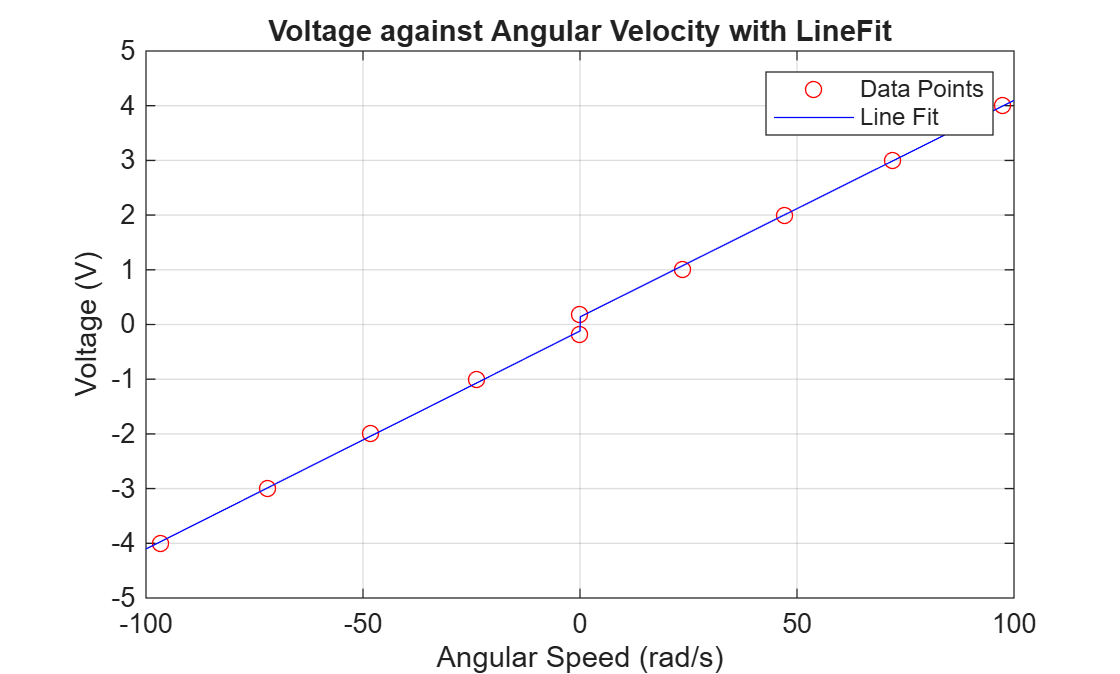

x_p = 0:0.001:100;
f_p=polyval(coeffs_p, x_p);

% Combining the linear line results into one for easier plotting
x = [x_n, x_p];
f = [f_n, f_p];

% Plotting the line fit with the data points in a blue line
plot(x, f, 'b')

% Adding title, axis labels, grid lines, and legend
title("Voltage against Angular Velocity with LineFit")
xlabel('Angular Speed (rad/s)')
ylabel('Voltage (V)')
grid on
legend("Data Points", "Line Fit")

hold off

6.2.5: Model Friction Validation

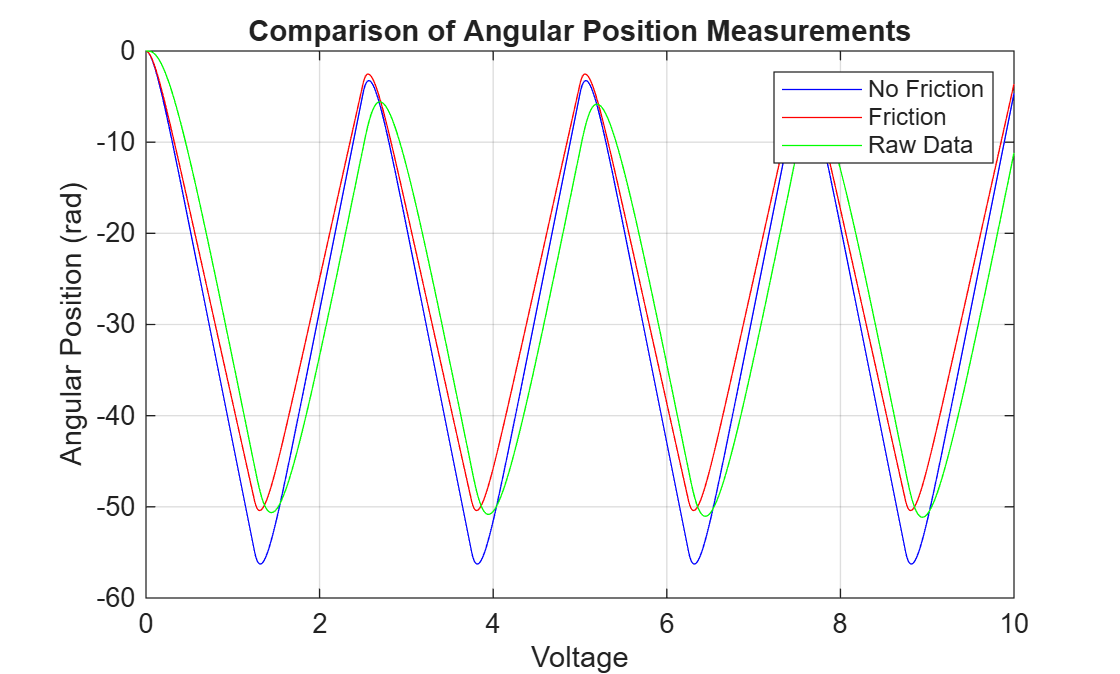

% Open the comparison figure
fig = openfig('Lab03_Group06_Comparison_Figure.fig');

% Find all plotted line objects
lines = findobj(fig, 'Type', 'Line');

% Extract X and Y data for each line object
% (Raw Data, No Friction, and Friction)
x1 = lines(1).XData;
y1 = lines(1).YData;
x2 = lines(2).XData;
y2 = lines(2).YData;
x3 = lines(3).XData;
y3 = lines(3).YData;

% The cumsum formula represents the cumulative sum using rectangular approximations.
% For y = f(x),  cumsum(y) * dx can be used to approximate the integral of
% the y with respect to x. For our problem, dx = 0.002 from the step size
% defined inside of the Simulink file.
% So, cumsum(y) = [y1, y1+y2, y1+y2+y3, ...] and dx = 0.002 so we can plot
% the result of cumsum(y) * dx which is the approximation of the integral.

% The cumsum function information is found at: https://www.mathworks.com/help/matlab/ref/double.cumsum.html

% Below is our implementation of this integral
integral_data1 = cumsum(y1)*(x1(2)-x1(1));
integral_data2 = cumsum(y2)*(x2(2)-x2(1));
integral_data3 = cumsum(y3)*(x3(2)-x3(1));

% Close the figure
close

% Plot the position data against input voltage
plot(x1, integral_data1, 'b')
hold on
plot(x2, integral_data2, 'r')
hold on
plot(x3, integral_data3, 'g')
hold on

% Adding title, axis labels, grid lines, and legend
xlabel('Voltage')
ylabel('Angular Position (rad)')
title('Comparison of Angular Position Measurements')
grid on
lgd = legend("No Friction", "Friction", "Raw Data");

hold off

6.3.8: Transfer Functions

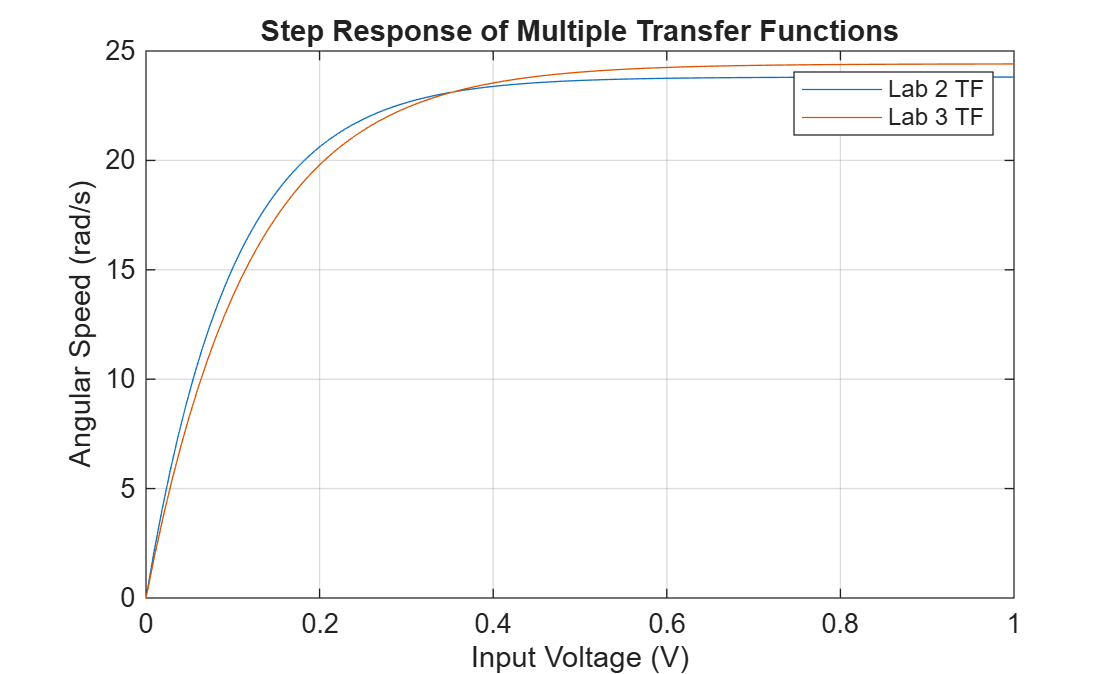

% Inputting the transfer functions from lab 2 and 3 using the "tf" function
sys1 = tf(1, [0.004179712, 0.042]);      % Lab 2 Transfer Function
sys2 = tf(1, [0.0049192225, 0.040961]);  % Lab 3 Transfer Function

% Use the step function of the transfer function and store the outputs
[w1, v1] = step(sys1, 1);
[w2, v2] = step(sys2, 1);

% Plot the step response of the output speed against the input voltage
plot(v1, w1);
hold on
plot(v2, w2);

% Adding title, axis labels, grid lines, and legend
title("Step Response of Multiple Transfer Functions")
xlabel("Input Voltage (V)")
ylabel("Angular Speed (rad/s)")
grid on
legend("Lab 2 TF", "Lab 3 TF")